**Create a Demonstration Lane System**

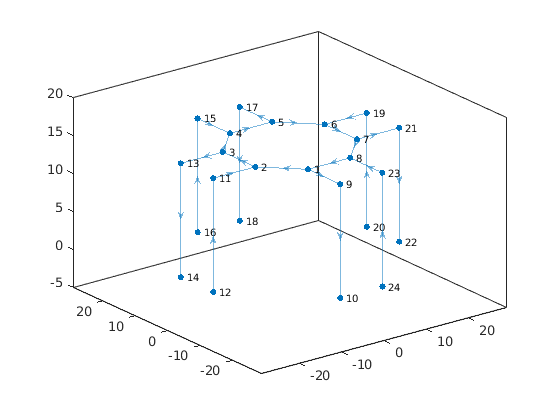

lbsd = LBSD.genSampleLanes(10, 15);

plot(lbsd);

**Create A Couple UAS**

num_uas = 5

num_uas = 5

uas_arr(num_uas) = UAS();
% The default ID of the uas class is a random
% uuid, so rename the ids to ints to make it
% easier to track. Also, give each uas a reference
% to the lbsd.
for i = 1:num_uas
    uas_arr(i).id = string(i);
    uas_arr(i).lbsd = lbsd;
end
uas_arr(1)

ans =   UAS with properties:

                     id: "1"
                    gps: [1×1 GPS]
                     kb: []
                   lbsd: [1×1 LBSD]
             climb_rate: 1
          nominal_speed: 1
           set_point_hz: 1
                res_ids: []
    telemetry_listeners: []


[traj, lane_ids, vert_ids, toa_s] = uas_arr(1).createTrajectory([-20,-20],[20,20]);

traj =   Trajectory with properties:

         trajectory: [1×1 waypointTrajectory]
           position: [0 0 0]
        orientation: []
    angularVelocity: [0 0 0]
           velocity: [0 0 0]
       acceleration: [0 0 0]
             time_s: 0
               f_hz: 1
           complete: 0


lane_ids = 7×1 string array
    "11"
    "12"
    "3"
    "4"
    "5"
    "17"
    "18"


vert_ids = 8×1 string array
    "12"
    "11"
    "2"
    "3"
    "4"
    "5"
    "17"
    "18"


toa_s =      0
    15
    25
    35
    45
    55
    65
    80
